# Groceries Dataset

Clear workspace

clear all; clc; close all;

## Load data

load groceries.mat

## Find frequent articles

minSup = 0.001;
tic
[F, S, items] = findFreqItemsets(gro,minSup)

F = 1×6 struct array with fields:
    freqSets


S =   Map with properties:

        Count: 101518
      KeyType: char
    ValueType: any


items = 169×1 cell array
    {'Instant food products'}
    {'UHT-milk'             }
    {'abrasive cleaner'     }
    {'artif. sweetener'     }
    {'baby cosmetics'       }
    {'baby food'            }
    {'bags'                 }
    {'baking powder'        }
    {'bathroom cleaner'     }
    {'beef'                 }
    {'berries'              }
    {'beverages'            }
    {'bottled beer'         }
    {'bottled water'        }
    {'brandy'               }
    {'brown bread'          }
    {'butter'               }
    {'butter milk'          }
    {'cake bar'             }
    {'candles'              }
    {'candy'                }
    {'canned beer'          }
    {'canned fish'          }
    {'canned fruit'         }
    {'canned vegetables'    }
    {'cat food'             }
    {'cereals'              }
    {'chewing gum'          }
    {'chicken'              }
    {'chocolate'            }


toc

Elapsed time is 141.374692 seconds.


## Generate rules

Establisha confidence level

minConf = 0.6;
tic
rules = generateRules(F,S,minConf)

rules = 1×2954 struct array with fields:
    Ante
    Conseq
    Conf
    Lift
    Sup


toc

Elapsed time is 10.834710 seconds.



fprintf('Confidence level: %.2f\n', minConf)

Confidence level: 0.60


fprintf('Rules encountered: %d\n\n', length(rules))

Rules encountered: 2954



### Print rules

% for i=1:length(rules)
%     disp([sprintf('{%s}',items{rules(i).Ante}), ' => ', ...
%           sprintf('{%s}',items{rules(i).Conseq}), ...
%           sprintf('      Conf: %.2f',rules(i).Conf), ...
%           sprintf('Lift: %.2f',rules(i).Lift), ...
%           sprintf('Sup: %.2f',rules(i).Sup)])
% end

### Plot main metrics

sup  = extractfield(rules,'Sup');
conf = extractfield(rules,'Conf');
lift = extractfield(rules,'Lift');

rulestbl = struct2table(rules);

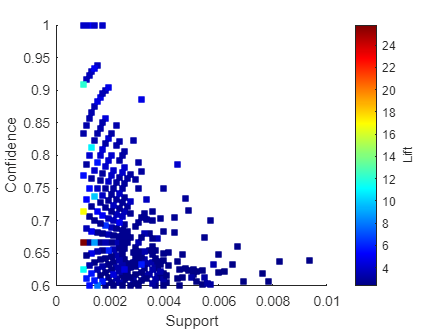

figure(1)
clf
hold on
colormap jet
scatter(sup,conf,[],lift,'s','filled')
a = colorbar;
a.Label.String = 'Lift';
xlabel('Support')
ylabel('Confidence')
hold off

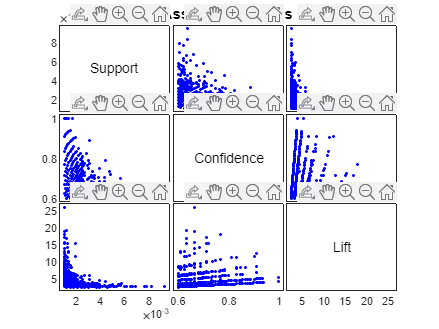

X = [sup' conf' lift'];
xnames = {'Support', 'Confidence', 'Lift'};

figure(2)
[h,ax] = gplotmatrix(X,[],[],[],[],7,[],variable=xnames);
title('Association Rules')